leaves(1).name = 'hibiscus';
leaves(1).class = 'dicotyledon';
leaves(1).type = 'simple';
leaves(1).shape = 'ovate';
leaves(1).venation = 'netted';
leaves(1).margin = 'serrated';
leaves(1).arrangement = 'alternate';
leaves(1).originalimage = imread('C:\Users\MUTESI FAITH\Desktop\assignment 3\hibiscus.jpeg')

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(1).grayimage = rgb2gray(leaves(1).originalimage);
leaves(1).adjustedimage = imadjust(leaves(1).grayimage);
threshold1 = graythresh(leaves(1).adjustedimage);
leaves(1).binarymask = imbinarize(leaves(1).adjustedimage,threshold1);
leaves(1).edgeimage = edge(leaves(1).grayimage,'canny');

leaves(2).name = 'cassava'

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(2).class = 'dicotyledon'

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(2).type = 'compound'

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(2).shape = 'palmatifid'

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(2).venation = 'palmate reticulate'

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(2).margin = 'entire'

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(2).arrangement = 'alternate'

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(2).originalimage = imread('C:\Users\MUTESI FAITH\Desktop\assignment 3\hibiscus.jpeg')

leaves = 1×2 struct array with fields:
    name
    class
    type
    shape
    venation
    margin
    arrangement
    originalimage
    grayimage
    adjustedimage
    binarymask
    edgeimage


leaves(2).grayimage = rgb2gray(leaves(2).originalimage);
leaves(2).adjustedimage = imadjust(leaves(2).grayimage);
threshold2 = graythresh(leaves(2).adjustedimage);
leaves(2).binarymask = imbinarize(leaves(2).adjustedimage,threshold1);
leaves(2).edgeimage = edge(leaves(2).grayimage,'canny');

for i = 1:length(leaves)
    fprintf('\nleaf %:d: %s\n',i,leaves(i).name);
    fprintf('class: %s\n',leaves(i).class);
    fprintf('type: %s\n',leaves(i).type);
    fprintf('shape: %s\n',leaves(i).shape);
    fprintf('venation: %s\n',leaves(i).venation);
    fprintf('margin: %s\n',leaves(i).margin);
    fprintf('arrangement: %s\n',leaves(i).arrangement);
end


leaf 

class: dicotyledon


type: simple


shape: ovate


venation: netted


margin: serrated


arrangement: alternate



leaf 

class: dicotyledon


type: compound


shape: palmatifid


venation: palmate reticulate


margin: entire


arrangement: alternate


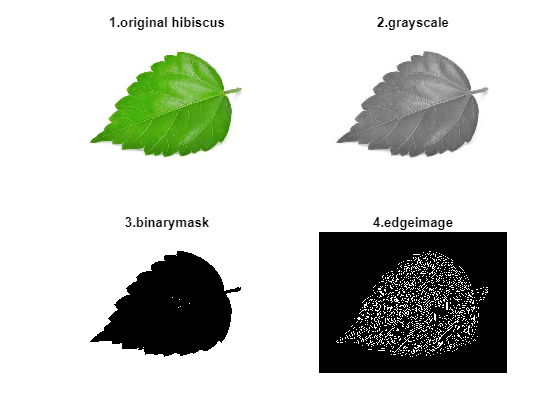

figure('Name','hibiscus image processing');
subplot(2,2,1);imshow(leaves(1).originalimage);title('1.original hibiscus');
subplot(2,2,2);imshow(leaves(1).grayimage);title('2.grayscale');
subplot(2,2,3);imshow(leaves(1).binarymask);title('3.binarymask');
subplot(2,2,4);imshow(leaves(1).edgeimage);title('4.edgeimage');

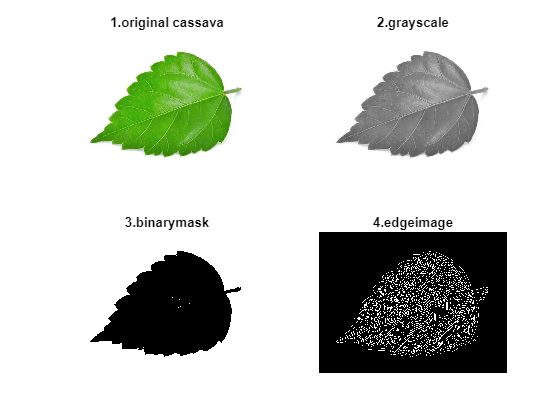

figure('Name','cassava image processing');
subplot(2,2,1);imshow(leaves(2).originalimage);title('1.original cassava');
subplot(2,2,2);imshow(leaves(2).grayimage);title('2.grayscale');
subplot(2,2,3);imshow(leaves(2).binarymask);title('3.binarymask');
subplot(2,2,4);imshow(leaves(2).edgeimage);title('4.edgeimage');